A = [-3 -1 0;
     -1 -2 -1;
     0 -1 -2];
B = [10;
     0;
     9];
C = [0 1 1];
D = [0];
[b_coeffs a_coeffs] = ss2tf(A, B, C, D)

b_coeffs =          0    9.0000   26.0000    8.0000


a_coeffs =     1.0000    7.0000   14.0000    7.0000


eig(A)

ans =    -3.8019
   -2.4450
   -0.7530


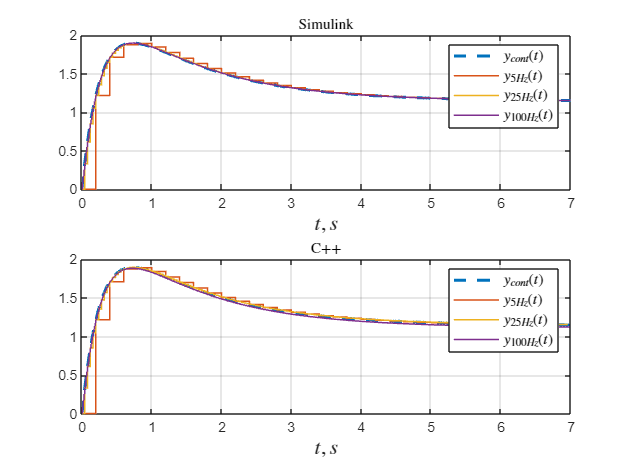

disc_intervals = [1/5 1/25 1/100];

A_d_array = cell(1, 3);
B_d_array = cell(1, 3);
for i = 1:3
    A_d_array{i} = expm(A * disc_intervals(i));
    B_d_array{i} = inv(A) * (expm(A * disc_intervals(i)) - eye(3)) * B;
end    

for i = 1:3
    A_d = A_d_array{i};
    B_d = B_d_array{i};

end  
simtime = 7;
simOut = sim('MIRSU.slx',simtime);
figure();
subplot(2,1,1)
plot_y_cont = plot(simOut.y_cont.time,simOut.y_cont.data, "LineStyle","--","LineWidth",2);
hold on
plot_y_5hz = stairs(simOut.y_5hz.time,simOut.y_5hz.data, "LineStyle","-","LineWidth",1);
hold on
plot_y_25hz = stairs(simOut.y_25hz.time,simOut.y_25hz.data, "LineStyle","-","LineWidth",1);
hold on
plot_y_100hz = stairs(simOut.y_100hz.time,simOut.y_100hz.data, "LineStyle","-","LineWidth",1);
xlabel('$t, s$',"Interpreter","latex", "FontSize", 14);
legend('$ y_{cont}(t) $','$ y_{5Hz}(t) $',"$y_{25Hz}(t)$", "$y_{100Hz}(t)$", "Interpreter", "latex", "FontSize", 10);
title("Simulink", "Interpreter","latex");
grid;

subplot(2,1,2)
T = readtable('cont.csv');
plot_y_cont_cpp = plot(T.t,T.y, "LineStyle","--","LineWidth",2);
hold on
T = readtable('5_hz.csv');
plot_y_5hz_cpp = stairs(T.t,T.y, "LineStyle","-","LineWidth",1);
hold on
T = readtable('25_hz.csv');
plot_y_25hz_cpp = stairs(T.t,T.y, "LineStyle","-","LineWidth",1);
hold on
T = readtable('100_hz.csv');
plot_y_100hz_cpp = stairs(T.t,T.y, "LineStyle","-","LineWidth",1);
xlabel('$t, s$',"Interpreter","latex", "FontSize", 14);
legend('$ y_{cont}(t) $','$ y_{5Hz}(t) $',"$y_{25Hz}(t)$", "$y_{100Hz}(t)$", "Interpreter", "latex", "FontSize", 10);
title("C++", "Interpreter","latex");
grid;